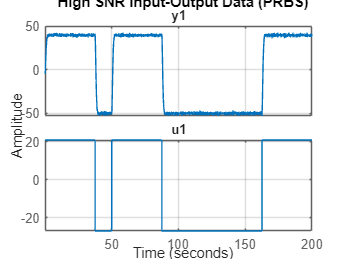

% ============================================================
%     MENG 3020 – FINAL PROJECT – PART A (Black-box Modelling)
%     Robot Arm-Link System Modeling & Identification
% ============================================================
% Dataset 17 below
B=4.559616926738720;
Bm=0.007052058673279;
g=9.810000000000000;
JG1=0.006991571816190;
JG2=0.099652027026338;
Jm=0.005574135299072;
Js1=0.046073254839203;
Js2=0.021931365993199;
Kb=0.877543876952904;
KT=0.877543876952904;
L=0.227699523910398;
La=0.078730828169049;
m=4.005658359474392;
N=5;
Ra=16.692387716797505;
Ts=0.050000000000000;
% =============
%   High SNR
% =============

% =============================
% 1) LOAD SIMULINK OUTPUT DATA
% =============================
aH = out.angleHigh;
vH = out.voltageHigh;

% =============================
% 2) CREATE IDDATA OBJECT
% =============================
data_HighSNR = iddata(aH, vH, Ts);
% Remove trend / offset
data_HighSNR = detrend(data_HighSNR);

figure;
plot(data_HighSNR)
title('High SNR Input-Output Data (PRBS)')
grid on


% =============================
% 3) SPLIT ID / VALIDATION DATA
% =============================

N_len = length(data_HighSNR.OutputData);

dataID_High  = data_HighSNR(1 : round(0.6*N_len));
dataVAL_High = data_HighSNR(round(0.6*N_len)+1 : end);

% =============================
% 4) INPUT DELAY ESTIMATION
% =============================
Hdelay = delayest(dataID_High)

Hdelay = 5

fprintf('\nEstimated Input Delay: %d samples\n', Hdelay);


Estimated Input Delay: 5 samples


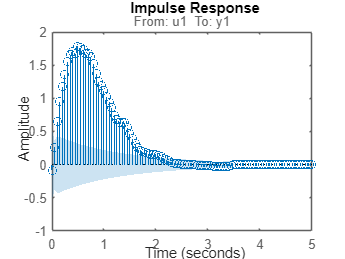


% =============================
% 5) MODEL ORDER ESTIMATION (HANKEL TEST)
% =============================
ImpRes = impulseest(data_HighSNR);
ImpRes_Plot = impulseplot(ImpRes);
showConfidence(ImpRes_Plot, 5)

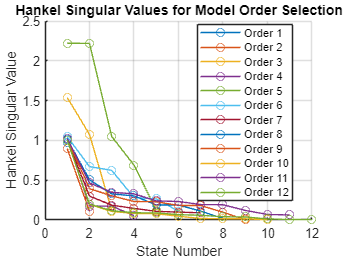

order_range = 1:12;
HSV = cell(length(order_range),1);

for i = 1:length(order_range)
    nx = order_range(i);

    sys_temp = n4sid(dataID_High, nx, 'InputDelay', Hdelay, 'DisturbanceModel', 'none');

    HSV{i} = hsvd(sys_temp);
end

figure; hold on;
for i = 1:length(order_range)
    plot(HSV{i}, '-o', 'DisplayName', ['Order ', num2str(order_range(i))]);
end
xlabel('State Number')
ylabel('Hankel Singular Value')
title('Hankel Singular Values for Model Order Selection')
legend('Location','best')
grid on

% =============================
% 6) SELECT MODEL STRUCTURE
% =============================

% Choose based on Hankel plot
np = 2;    % number of poles  (ADJUST if needed)
nz = 1;    % number of zeros  (ADJUST if needed)
nk = Hdelay;

sysH = tfest(dataID_High, np, nz, nk);

disp('Identified Transfer Function Model:')

Identified Transfer Function Model:


present(sysH);

                                                                                                                                                                                                                                                                                               
sysHH =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

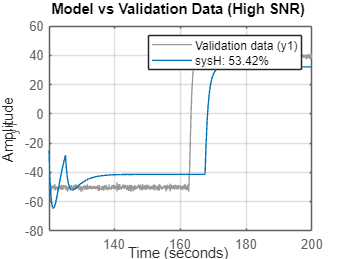

% =============================
% 7) MODEL VALIDATION
% =============================

figure
compare(dataVAL_High, sysH, Inf)
title('Model vs Validation Data (High SNR)')
grid on

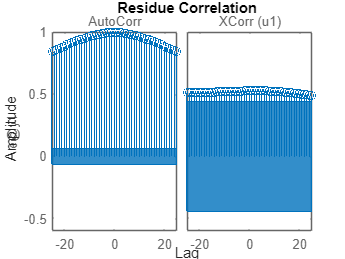

% =============================
% 8) RESIDUAL ANALYSIS
% =============================

figure
resid(dataVAL_High, sysH)

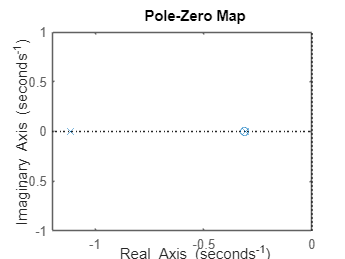


% =============================
% 9) POLE-ZERO MAP
% =============================

pzmap(sysH)


% =============================
% 10) DC GAIN
% =============================

K_dc = dcgain(sysH);
fprintf('\nDC Gain of Identified Model = %.4f\n', K_dc);


DC Gain of Identified Model = 1.5302


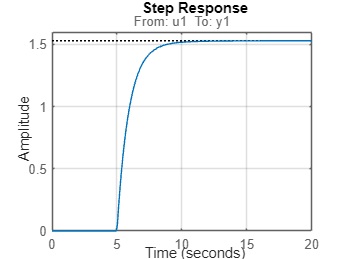


% =============================
% 11) STEP RESPONSE
% =============================

figure
stepplot(sysH)
grid on

info = stepinfo(sysH);
[y, ~] = step(sysH);
steady_state = y(end);

disp('Step Response Information:');disp(info);fprintf('Steady-State Value: %.4f\n', steady_state);

Step Response Information:
         RiseTime: 2.0477
    TransientTime: 8.8217
     SettlingTime: 8.8217
      SettlingMin: 1.3823
      SettlingMax: 1.5298
        Overshoot: 0
       Undershoot: 0
             Peak: 1.5298
         PeakTime: 19.7148

Steady-State Value: 1.5298


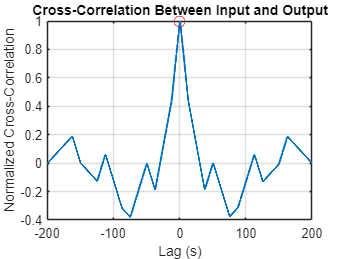



% =============================
% 12) CROSS CORRELATION CHECK
% =============================

[Hcorrelation, Hlags] = xcorr(aH, vH, 'normalized');
[Hmax_corr, Hmax_idx] = max(Hcorrelation);

figure
plot(Hlags*Ts, Hcorrelation, 'LineWidth', 1.5)
hold on
plot(Hlags(Hmax_idx)*Ts, Hmax_corr, 'ro', 'MarkerSize', 8)
xlabel('Lag (s)')
ylabel('Normalized Cross-Correlation')
title('Cross-Correlation Between Input and Output')
grid on
hold off

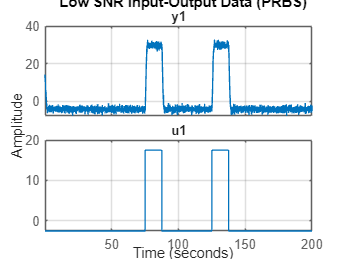


% =============
%   Low SNR
% =============

% =============================
% 14) LOAD SIMULINK OUTPUT DATA
% =============================
aL = out.angleLow;
vL = out.voltageLow;

% =============================
% 15) CREATE IDDATA OBJECT
% =============================
data_LowSNR = iddata(aL, vL, Ts);
% Remove trend / offset
data_LowSNR = detrend(data_LowSNR);

figure;
plot(data_LowSNR)
title('Low SNR Input-Output Data (PRBS)')
grid on


% =============================
% 16) SPLIT ID / VALIDATION DATA
% =============================

NL = length(data_LowSNR.OutputData);

dataID_low  = data_LowSNR(1 : round(0.6*NL));
dataVAL_low = data_LowSNR(round(0.6*NL)+1 : end);

% =============================
% 17) INPUT DELAY ESTIMATION
% =============================
Ldelay = delayest(dataID_low)

Ldelay = 7

fprintf('\nEstimated Input Delay: %d samples\n', Ldelay);


Estimated Input Delay: 7 samples


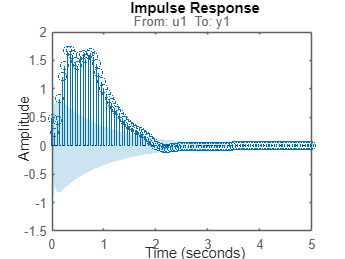


% =============================
% 18) MODEL ORDER ESTIMATION (HANKEL TEST)
% =============================
ImpResL = impulseest(data_LowSNR);
ImpRes_PlotL = impulseplot(ImpResL);
showConfidence(ImpRes_PlotL, 5)

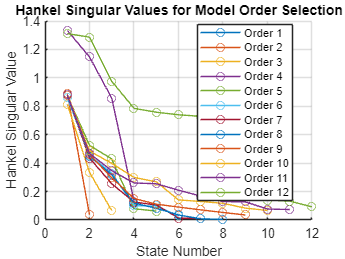

order_range = 1:12;
HSV = cell(length(order_range),1);

for i = 1:length(order_range)
    nx = order_range(i);

    Lsys_temp = n4sid(dataID_low, nx, 'InputDelay', Ldelay, 'DisturbanceModel', 'none');

    HSV{i} = hsvd(Lsys_temp);
end

figure; hold on;
for i = 1:length(order_range)
    plot(HSV{i}, '-o', 'DisplayName', ['Order ', num2str(order_range(i))]);
end
xlabel('State Number')
ylabel('Hankel Singular Value')
title('Hankel Singular Values for Model Order Selection')
legend('Location','best')
grid on


% =============================
% 19) SELECT MODEL STRUCTURE
% =============================

% Choose based on Hankel plot
np = 2;    % number of poles  (ADJUST if needed)
nz = 1;    % number of zeros  (ADJUST if needed)
nk = Ldelay;

sysL = tfest(dataID_low, np, nz, nk);

disp('Identified Transfer Function Model:')

Identified Transfer Function Model:


present(sysL);

                                                                                                                                                                                                                                                                                               
sysLL =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

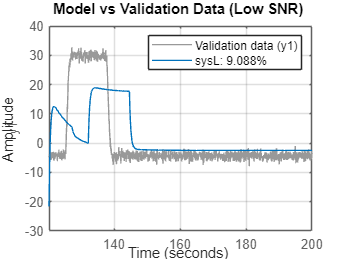

% =============================
% 20) MODEL VALIDATION
% =============================

figure
compare(dataVAL_low, sysL, Inf)
title('Model vs Validation Data (Low SNR)')
grid on

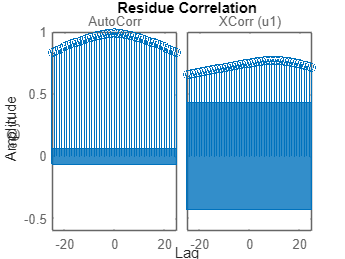

% =============================
% 21) RESIDUAL ANALYSIS
% =============================

figure
resid(dataVAL_low, sysL)

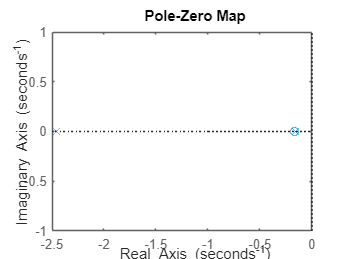


% =============================
% 22) POLE-ZERO MAP
% =============================

pzmap(sysL)


% =============================
% 23) DC GAIN
% =============================

LK_dc = dcgain(sysL);
fprintf('\nDC Gain of Identified Model = %.4f\n', LK_dc);


DC Gain of Identified Model = 0.9943


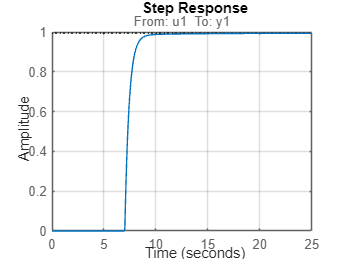


% =============================
% 24) STEP RESPONSE
% =============================

figure
stepplot(sysL)
grid on

Linfo = stepinfo(sysL, 'YFinal', dcgain(sysL));
[y, ~] = step(sysL);
Lsteady_state = y(end);
disp('Step Response Information:');disp(Linfo);fprintf('Steady-State Value: %.4f\n', Lsteady_state);

Step Response Information:
         RiseTime: 0.9257
    TransientTime: 8.7755
     SettlingTime: 8.7755
      SettlingMin: 0.8979
      SettlingMax: 0.9931
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9931
         PeakTime: 20.1997

Steady-State Value: 0.9931


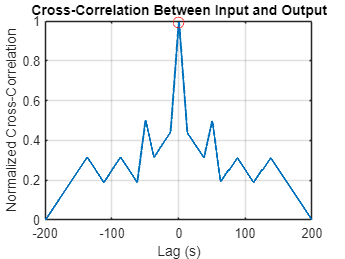



% =============================
% 25) CROSS CORRELATION CHECK
% =============================

[Lcorrelation, Llags] = xcorr(aL, vL, 'normalized');
[Lmax_corr, Lmax_idx] = max(Lcorrelation);

figure
plot(Llags*Ts, Lcorrelation, 'LineWidth', 1.5)
hold on
plot(Llags(Lmax_idx)*Ts, Lmax_corr, 'ro', 'MarkerSize', 8)
xlabel('Lag (s)')
ylabel('Normalized Cross-Correlation')
title('Cross-Correlation Between Input and Output')
grid on
hold off

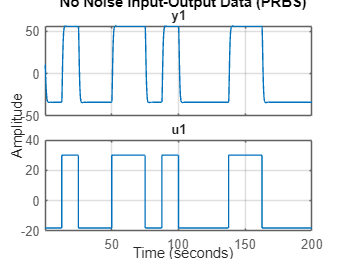



% =============
%   No Noise
% =============

% =============================
% 1) LOAD SIMULINK OUTPUT DATA
% =============================
aNN = out.angleNN;
vNN = out.voltageNN;

% =============================
% 2) CREATE IDDATA OBJECT
% =============================
data_NN = iddata(aNN, vNN, Ts);
% Remove trend / offset
data_NN = detrend(data_NN);

figure;
plot(data_NN)
title('No Noise Input-Output Data (PRBS)')
grid on


% =============================
% 3) SPLIT ID / VALIDATION DATA
% =============================

NN = length(data_NN.OutputData);

dataID_NN  = data_NN(1 : round(0.6*NN));
dataVAL_NN = data_NN(round(0.6*NN)+1 : end);

% =============================
% 4) INPUT DELAY ESTIMATION
% =============================
NNdelay = delayest(dataID_NN)

NNdelay = 1

fprintf('\nEstimated Input Delay: %d samples\n', NNdelay);


Estimated Input Delay: 1 samples


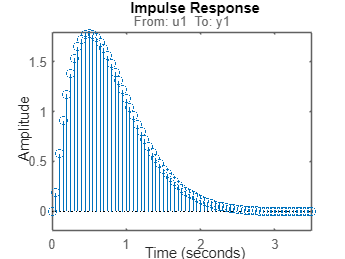


% =============================
% 5) MODEL ORDER ESTIMATION (HANKEL TEST)
% =============================
ImpResN = impulseest(data_NN);
ImpRes_PlotN = impulseplot(ImpResN);
showConfidence(ImpRes_PlotN, 5)

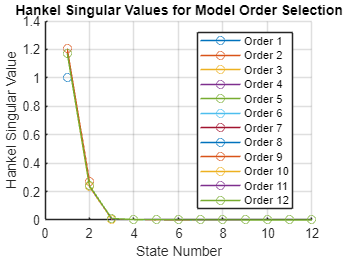

order_range = 1:12;
HSV = cell(length(order_range),1);

for i = 1:length(order_range)
    nx = order_range(i);

    Nsys_temp = n4sid(dataID_NN, nx, 'InputDelay', NNdelay, 'DisturbanceModel', 'none');

    HSV{i} = hsvd(Nsys_temp);
end

figure; hold on;
for i = 1:length(order_range)
    plot(HSV{i}, '-o', 'DisplayName', ['Order ', num2str(order_range(i))]);
end
xlabel('State Number')
ylabel('Hankel Singular Value')
title('Hankel Singular Values for Model Order Selection')
legend('Location','best')
grid on

% =============================
% 6) SELECT MODEL STRUCTURE
% =============================

% Choose based on Hankel plot
np = 2;    % number of poles  (ADJUST if needed)
nz = 1;    % number of zeros  (ADJUST if needed)
nk = NNdelay;

sysNN = tfest(dataID_NN, np, nz, nk);

disp('Identified Transfer Function Model:')

Identified Transfer Function Model:


present(sysNN);

                                                                                                                                                                                                                                                                                                    
sysNNNN =                                                                                                                                                                                                                                                                                           
                                                                                                                                                                                                                                                                                                    
  From input "u1" to output "y1":                                                                                        

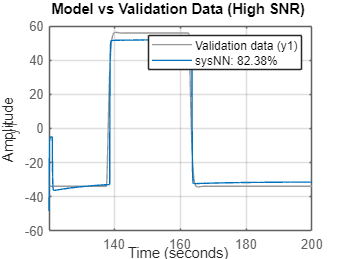

% =============================
% 7) MODEL VALIDATION
% =============================

figure
compare(dataVAL_NN, sysNN, Inf)
title('Model vs Validation Data (High SNR)')
grid on

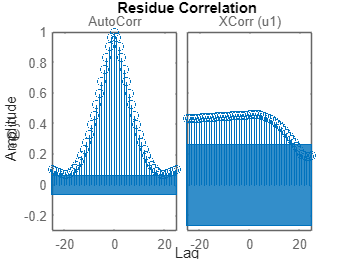

% =============================
% 8) RESIDUAL ANALYSIS
% =============================

figure
resid(dataVAL_NN, sysNN)

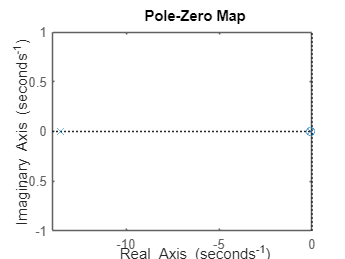


% =============================
% 9) POLE-ZERO MAP
% =============================

pzplot(sysNN)


% =============================
% 10) DC GAIN
% =============================

NK_dc = dcgain(sysNN);
fprintf('\nDC Gain of Identified Model = %.4f\n', NK_dc);


DC Gain of Identified Model = 1.7370


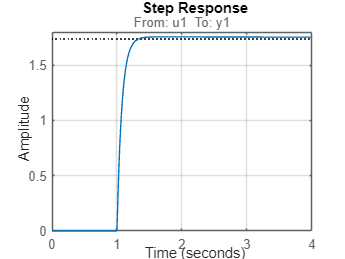


% =============================
% 11) STEP RESPONSE
% =============================

figure
stepplot(sysNN)
grid on

Ninfo = stepinfo(sysNN);
[y, t] = step(sysNN);
Nsteady_state = y(end);
disp('Step Response Information:');disp(Ninfo);fprintf('Steady-State Value: %.4f', Nsteady_state);

Step Response Information:
         RiseTime: 0.1549
    TransientTime: 1.2561
     SettlingTime: 1.2561
      SettlingMin: 1.5777
      SettlingMax: 1.7561
        Overshoot: 1.0982
       Undershoot: 0
             Peak: 1.7561
         PeakTime: 1.7186

Steady-State Value: 1.7533

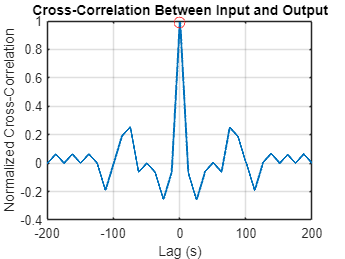



% =============================
% 12) CROSS CORRELATION CHECK
% =============================

[Ncorrelation, Nlags] = xcorr(aNN, vNN, 'normalized');
[max_corr, Nmax_idx] = max(Ncorrelation);

figure
plot(Nlags*Ts, Ncorrelation, 'LineWidth', 1.5)
hold on
plot(Nlags(Nmax_idx)*Ts, max_corr, 'ro', 'MarkerSize', 8)
xlabel('Lag (s)')
ylabel('Normalized Cross-Correlation')
title('Cross-Correlation Between Input and Output')
grid on
hold off


% =============================
% END OF PART A
% =============================